## Question 5

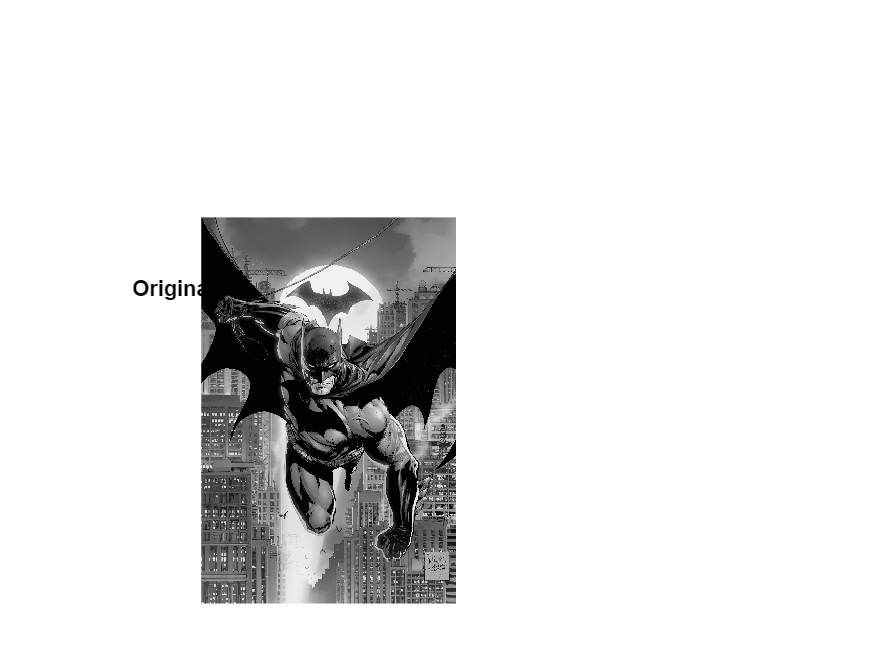

img = imread('Bat.jpg');
gray_img = rgb2gray(img);
figure, imshow(gray_img);
title('Original Grayscale Image');

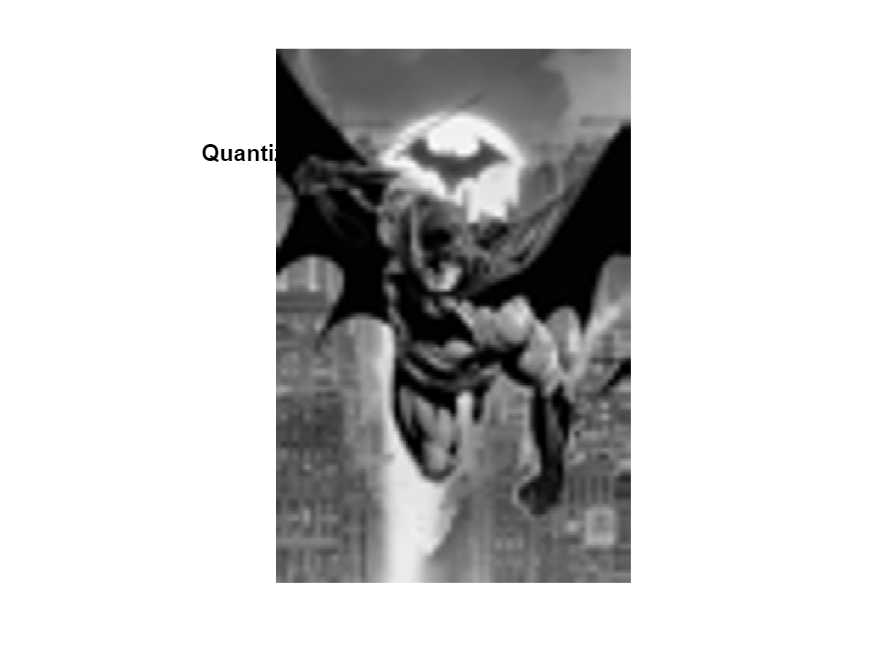

quantized_img = imresize(imresize(gray_img, 1/32), 32);
figure, imshow(quantized_img);
title('Quantized to 32 Levels Image');

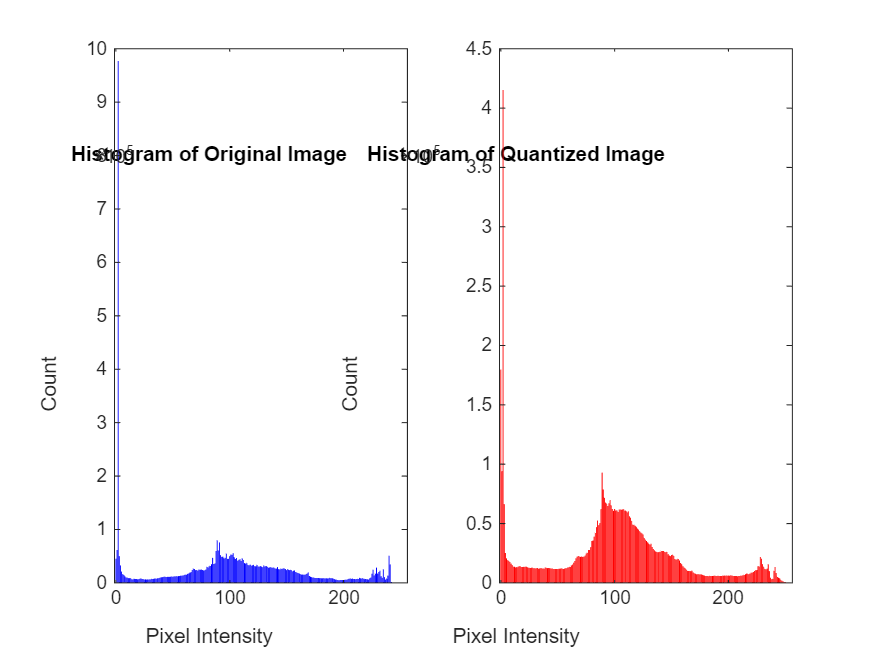

[hist_orig, orig_bins] = imhist(gray_img);
[hist_quant, quant_bins] = imhist(quantized_img);

figure;
subplot(1,2,1);
bar(orig_bins, hist_orig, 'b');
title('Histogram of Original Image');
xlabel('Pixel Intensity'); ylabel('Count');

subplot(1,2,2);
bar(quant_bins, hist_quant, 'r');
title('Histogram of Quantized Image');
xlabel('Pixel Intensity'); ylabel('Count');

disp('Histogram Values for Original Image:');

Histogram Values for Original Image:


disp([orig_bins, hist_orig]);

           0       45146
           1       61503
           2      976939
           3       50033
           4       32732
           5       21179
           6       16502
           7       15117
           8       12287
           9        9819
          10        9822
          11        8988
          12        9001
          13        9019
          14        6758
          15        6805
          16        7482
          17        7603
          18        7402
          19        6870
          20        6884
          21        7630
          22        8525
          23        7241
          24        6858
          25        6505
          26        6552
          27        6401
          28        6320
          29        6348
          30        6711
          31        7080
          32        7623
          33        7870
          34        7970
          35        8058
          36        8298
          37        8764
          38        9203
          39       10152


disp('Histogram Values for Quantized Image:');

Histogram Values for Quantized Image:


disp([quant_bins, hist_quant]);

           0      179741
           1       94168
           2      415225
           3       66344
           4       25193
           5       20674
           6       19117
           7       18575
           8       17663
           9       16386
          10       15208
          11       13760
          12       13568
          13       13110
          14       13146
          15       13573
          16       14161
          17       13801
          18       13461
          19       13427
          20       13545
          21       13477
          22       13774
          23       13427
          24       12814
          25       12797
          26       12687
          27       12742
          28       12791
          29       12417
          30       12328
          31       12293
          32       12597
          33       12057
          34       12272
          35       12418
          36       12313
          37       12125
          38       11981
          39       12859


disp('Explanation of the Quantization Process:');

Explanation of the Quantization Process:


disp('Quantization is the process of reducing the number of colors or grayscale levels in an image to a limited set. Here, we reduce the original grayscale image to 32 levels.');

Quantization is the process of reducing the number of colors or grayscale levels in an image to a limited set. Here, we reduce the original grayscale image to 32 levels.


disp('This is achieved using the imresize function, a method often used for image resizing. By first resizing the image to a much lower resolution and then back up, we effectively reduce the distinct pixel values due to interpolation.');

This is achieved using the imresize function, a method often used for image resizing. By first resizing the image to a much lower resolution and then back up, we effectively reduce the distinct pixel values due to interpolation.


disp('The first imresize reduces the resolution, compressing the pixel values into fewer clusters. Resizing it back up scales it to the original size but with fewer unique values, achieving quantization.');

The first imresize reduces the resolution, compressing the pixel values into fewer clusters. Resizing it back up scales it to the original size but with fewer unique values, achieving quantization.


disp('The histograms of the original and quantized images illustrate the reduction in levels. The original image''s histogram shows a smooth distribution of grayscale values, while the quantized image''s histogram has fewer peaks, indicating fewer grayscale levels.');

The histograms of the original and quantized images illustrate the reduction in levels. The original image's histogram shows a smooth distribution of grayscale values, while the quantized image's histogram has fewer peaks, indicating fewer grayscale levels.


disp('This technique is particularly useful in applications where memory bandwidth is a constraint, or for stylistic effects in graphics design.');

This technique is particularly useful in applications where memory bandwidth is a constraint, or for stylistic effects in graphics design.
